# Задание 1

&&&ТЕКСТ ЗАДАНИЯ+входные воздействия&&&

Возьмём структурную схему из **Задания 1 Лабораторной работы 2** для наших входных значений  $u(t)$ (см. рис. &&&). 

&&&РИСУНОК

&&&РИСУНОК

&&&РИСУНОК

Рассмотрим второй, третий и четвертый набор коэффициентов $a_0, a_1$, рассчитанных в рамках **Задания 1 Лаб. работы 2**:

`№  a_1		 a_0`

`2   7.400	 38.690`

`3   0.000	841.000`

`4  -1.400	 25.490`

`Выполним для них моделирование движения системы согласно данным нам начальным условиям и входным воздействиям и посмотрим на полученные графики:`

- `Набор 2 на рис. &&& - &&&`

&&&РИСУНОК

- `Набор 3 на рис. &&& - &&&`

&&&РИСУНОК

- `Набор 4 на рис. &&& - &&&`

&&&РИСУНОК

**Анализ и выводы**

`При каждом из входных воздействий мы видим, что для любых взятых нами начальных условий 2-й набор коэффициентов делает систему ассимптотически устойчивой, 3-й - граница устойчивости и  4-й - делает систему неуйстойчивой. На рисунках видно, что при ассимптотической устойчивости графики систем со временем сходятся к функции входного воздействия, при границе усточивости колеблются в некоторой окрестности и при неустойчивости убегают от вида функции входного воздействия. Таким образом, в данном задании мы довольно наглядно на эксперименте проверили выводы из предыдущей лабораторной работы о том, при каких коэффициентах какой устойчивостью система обладает.`

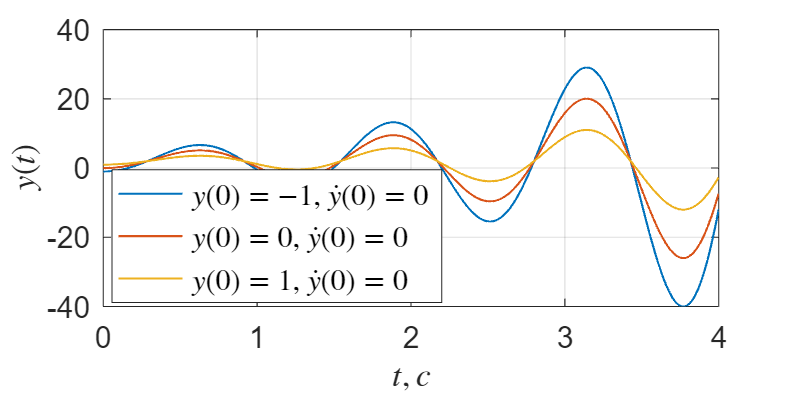

a1_a0_arr = [ [7.4 38.69]; [0 841]; [-1.4 25.49] ];
y0_dot_y0_arr = [ [-1 0]; [0 0]; [1 0] ];

simtime = 4;

for i=1:3
    a_1 = a1_a0_arr(i,1);
    a_0 = a1_a0_arr(i,2);
    for k=1:3
        y_0 = y0_dot_y0_arr(k,1);
        dot_y_0 = y0_dot_y0_arr(k,2);
    
        plot_1 = sim("lab3_1_1.slx", simtime);
        plot(plot_1.y.Time, plot_1.y.Data, LineWidth=1, LineStyle="-", ...
            DisplayName=sprintf('$y(0)=%d, \\dot{y}(0)=%d$', y_0, dot_y_0));
        hold on;
    
    end
    grid on;
    legend(Location="best", FontSize=14, Interpreter="latex");
    xlabel("$t, c$", Interpreter="latex");
    ylabel("$y(t)$", Interpreter="latex");
    set(gcf, Position=[100, 100, 1200, 600]);   
    set(gca, FontSize=14);
    
    hold off;
    filename = sprintf('images/plot_1_u2_%d.png', i);
    exportgraphics(gcf, filename, 'Resolution', 200)
end

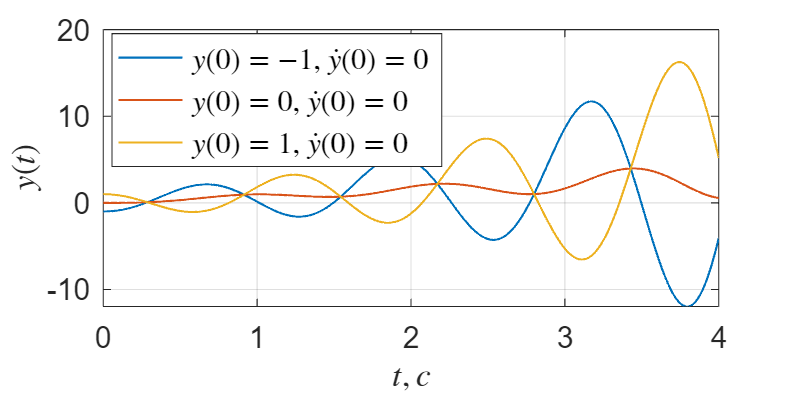


for i=1:3
    a_1 = a1_a0_arr(i,1);
    a_0 = a1_a0_arr(i,2);
    for k=1:3
        y_0 = y0_dot_y0_arr(k,1);
        dot_y_0 = y0_dot_y0_arr(k,2);
    
        plot_1 = sim("lab3_1_2.slx", simtime);
        plot(plot_1.y.Time, plot_1.y.Data, LineWidth=1, LineStyle="-", ...
            DisplayName=sprintf('$y(0)=%d, \\dot{y}(0)=%d$', y_0, dot_y_0));
        hold on;
    
    end
    grid on;
    legend(Location="best", FontSize=14, Interpreter="latex");
    xlabel("$t, c$", Interpreter="latex");
    ylabel("$y(t)$", Interpreter="latex");
    set(gcf, Position=[100, 100, 1200, 600]);   
    set(gca, FontSize=14);
    
    hold off;
    filename = sprintf('images/plot_1_u07t_%d.png', i);
    exportgraphics(gcf, filename, 'Resolution', 200)
end

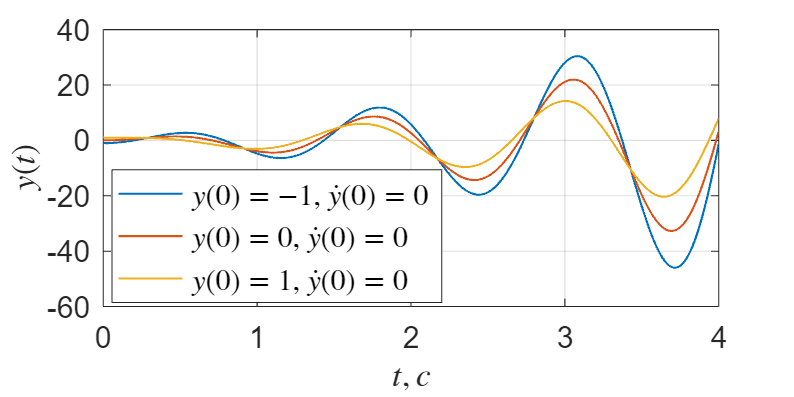


for i=1:3
    a_1 = a1_a0_arr(i,1);
    a_0 = a1_a0_arr(i,2);
    for k=1:3
        y_0 = y0_dot_y0_arr(k,1);
        dot_y_0 = y0_dot_y0_arr(k,2);
    
        plot_1 = sim("lab3_1_3.slx", simtime);
        plot(plot_1.y.Time, plot_1.y.Data, LineWidth=1, LineStyle="-", ...
            DisplayName=sprintf('$y(0)=%d, \\dot{y}(0)=%d$', y_0, dot_y_0));
        hold on;
    
    end
    grid on;
    legend(Location="best", FontSize=14, Interpreter="latex");
    xlabel("$t, c$", Interpreter="latex");
    ylabel("$y(t)$", Interpreter="latex");
    set(gcf, Position=[100, 100, 1200, 600]);   
    set(gca, FontSize=14);
    
    hold off;
    filename = sprintf('images/plot_1_ucos4t_%d.png', i);
    exportgraphics(gcf, filename, 'Resolution', 200)
end

# Задание 2

 Для системы 3-го порядка, заданной передаточной функцией


$$W(s) = \frac{|\lambda_1\lambda_2\lambda_3|}{(s - \lambda_1)(s - \lambda_2)(s - \lambda_3)},$$


исследуем зависимости качества переходной характеристики от выбора полюсов передаточной функции, для оценки качества используем такие показатели, как **перерегулирование** и **время переходного процесса**. Для этого зададимся **шестью** наборами полюсов $\lambda_1, \lambda_2$ и $\lambda_3$ с отрицательной вещественной частью. Половину наборов возьмем чисто вещественной, а во вторую половину включим комплексно-сопряженные полюса. В ходе исследования рекомендуется начинать с корней, имеющих равные вещественные части, а затем, фиксируя один или пару корней из набора, варьировать остальные. Проведем моделирование для выбранных наборов полюсов, определим значения времени переходных процессов и перерегулирования для каждого случая, сопоставим полученные результаты и сделаем выводы. Также сравним полученные значения перерегулирования с их верхними оценками на основании степени колебательности.

Выберем следующие набора полюсов $\lambda_1, \lambda_2, \lambda_2$: $\{\{-1,-1,-1\},\{-1,-1,-3\},\{-1,-3,-5\},\{-1,-1+i,-1-i\},\{-1, -3+i,-3-i\},\{-5,-3+i,-3-i\}\}$

Их расположение на комплексной плоскости на рисунках &&&-&&&.

&&&РИСУНОК

&&&РИСУНОК

&&&РИСУНОК

&&&РИСУНОК

&&&РИСУНОК

&&&РИСУНОК

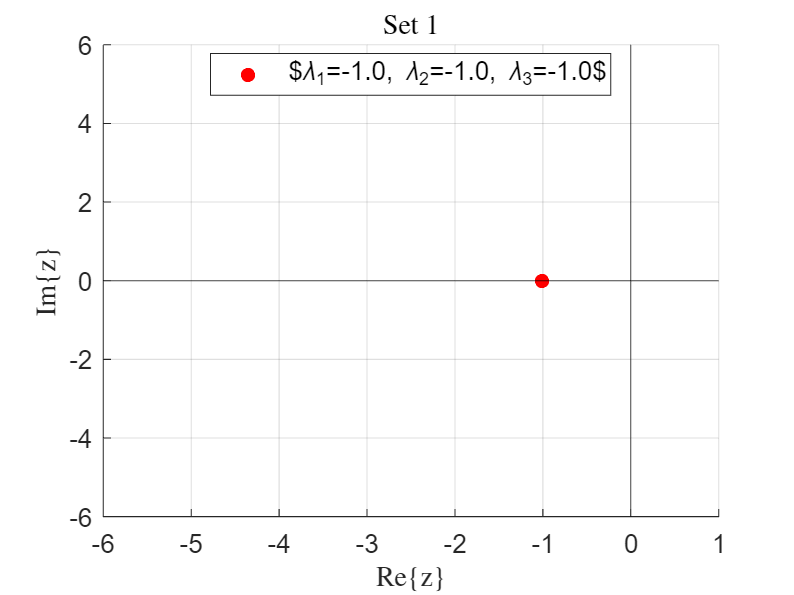

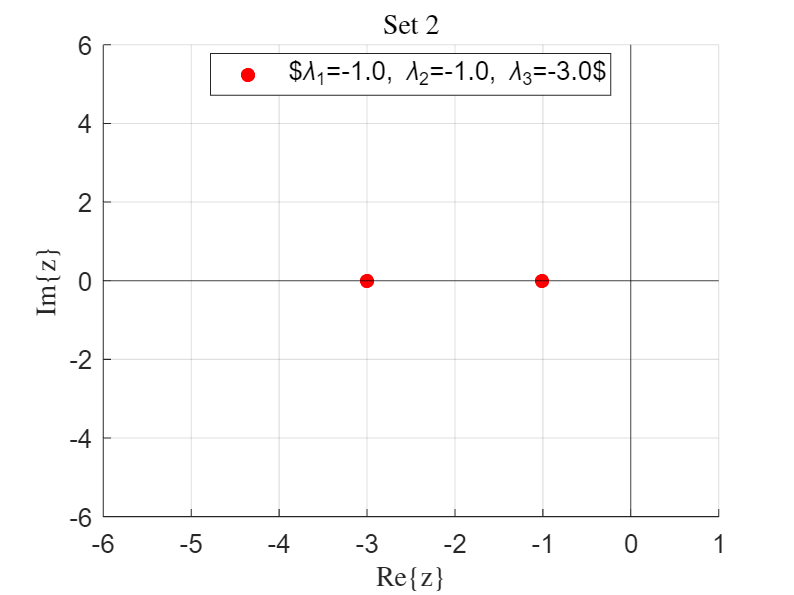

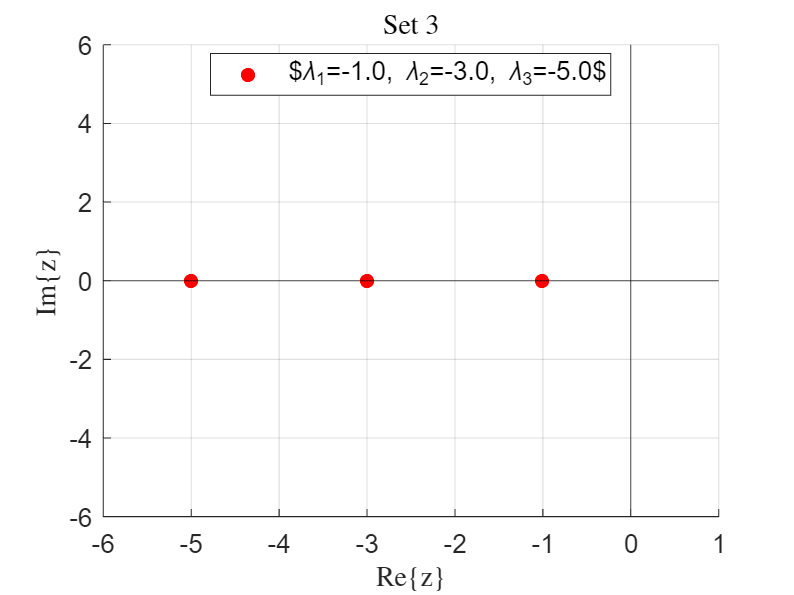

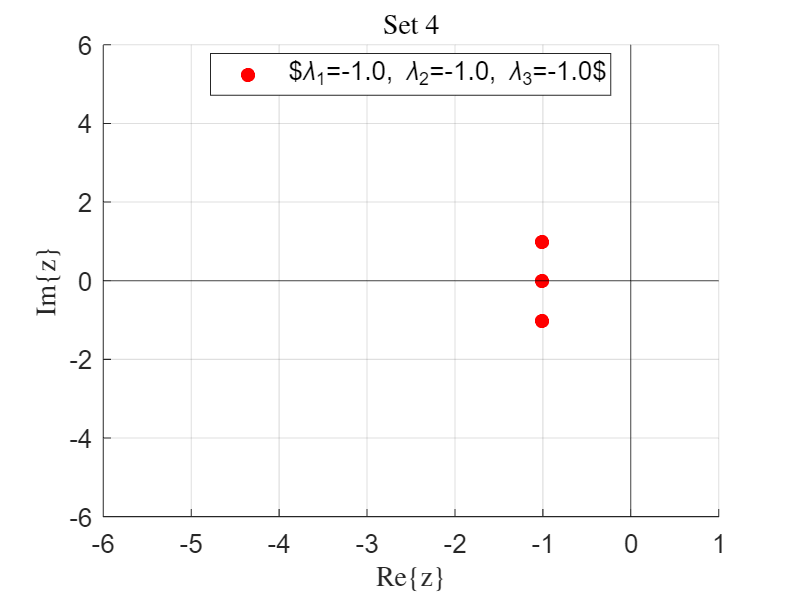

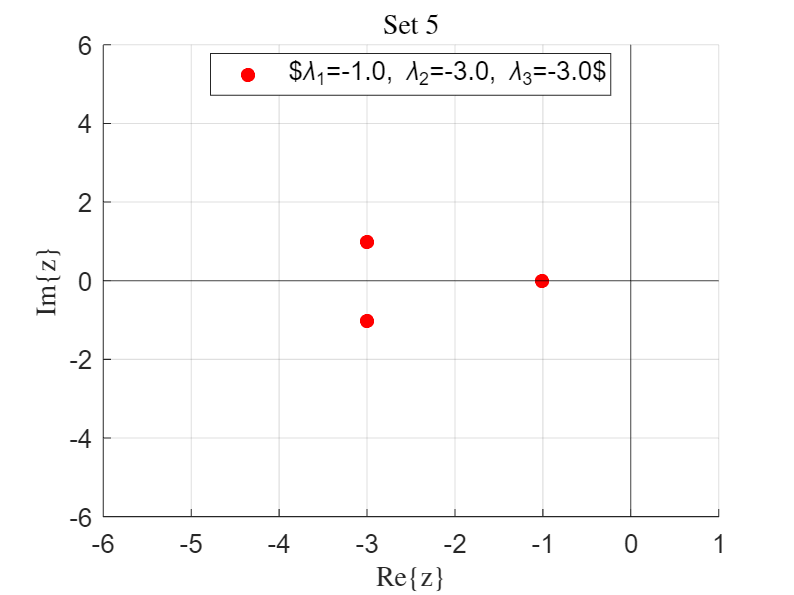

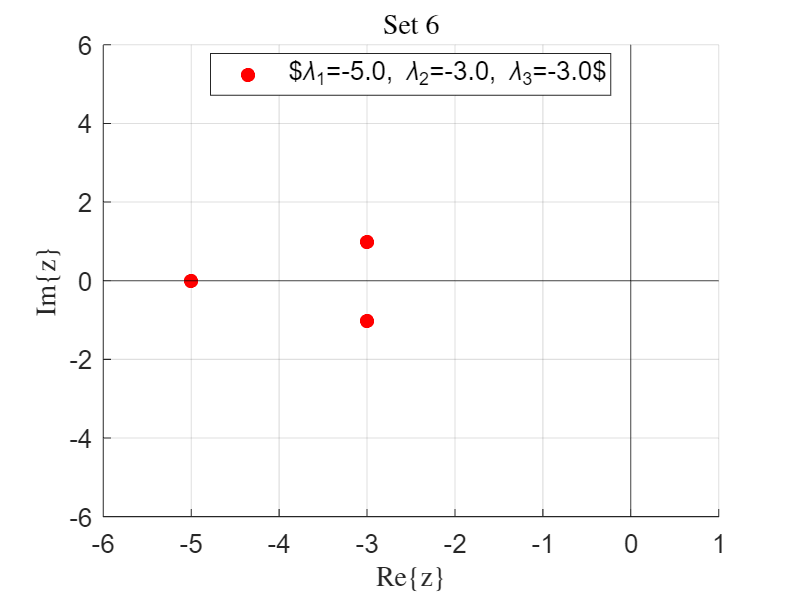

poles = [
    [-1, -1, -1];
    [-1, -1, -3];
    [-1, -3, -5];
    [-1, -1+1i, -1-1i];
    [-1, -3+1i, -3-1i];
    [-5, -3+1i, -3-1i]
];


for i = 1:6
    current_poles = poles(i,:);
    
    figure;
    xline(0, color="black", linestyle='-', LineWidth=0.5, HandleVisibility='off');
    hold on;
    yline(0, color="black", linestyle='-', LineWidth=0.5, HandleVisibility='off');
    hold on;
    plot(real(current_poles), imag(current_poles), 'r.', MarkerSize=20, ...
        DisplayName=sprintf('$\\lambda_{1}=%.1f, \\lambda_{2}=%.1f, \\lambda_{3}=%.1f$', ...
        real(current_poles(1)), real(current_poles(2)), real(current_poles(3))));
  
    grid on;
    xlabel("Re\{z\}", Interpreter="latex");
    ylabel("Im\{z\}", Interpreter="latex");
    title(sprintf('Set %d', i), Interpreter="latex");
    legend(Location="best", FontSize=12);
    set(gcf, Position=[100, 100, 800, 600]);
    set(gca, FontSize=12);
    xlim([-6.0, 1.0]);
    ylim([-6.0, 6.0]);
    hold off;
    
    filename = sprintf('images/poles_%d.png', i);
    exportgraphics(gcf, filename, 'Resolution', 200);
end

t = 0:0.001:10; 
u = ones(size(t));

for i = 1:6
    lambda_1 = poles(i,1);
    lambda_2 = poles(i,2);
    lambda_3 = poles(i,3);

    W = zpk([], [lambda_1, lambda_2, lambda_3], abs(lambda_1*lambda_2*lambda_3));
    y = lsim(W, u, t);

    figure;
    plot(t, y, 'LineWidth', 2, 'LineStyle', '-');
    grid on;
    ylabel("$y(t)$", Interpreter="latex");
    xlabel("$t, c$", Interpreter="latex");
    title(sprintf('Set %d', i), Interpreter="latex");
    legend(Location="best", FontSize=12);
    set(gcf, Position=[100, 100, 1200, 600]);
    set(gca, FontSize=12);
    
    filename = sprintf('images/per_proc_%d.png', i);
    exportgraphics(gcf, filename, 'Resolution', 200);
end

zpk requires one of the following:
  Control System Toolbox
  DSP System Toolbox
  Model Predictive Control Toolbox
  RF Toolbox
  Signal Processing Toolbox